% Read raw and calibrated gyro data
rawData = dlmread('rawgyrodata_final.txt', '\t'); %#ok<DLMRD>
calData = dlmread('calgyrodata_final.txt', '\t'); %#ok<DLMRD>
time_units = 's'; % Units of gyroscope measurements (used for axis labels)
gyro_units = 'rad/s';  % Units of gyroscope measurements (used for axis labels)
t = 1:1:50; % Set up our time measurements for axis

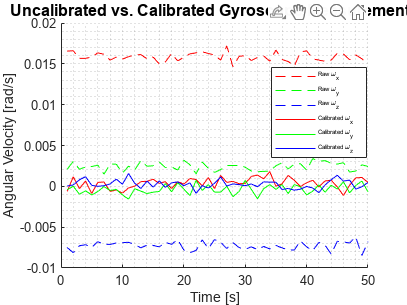

% Make all plots on same figure
figure;
hold on
grid minor

% Raw Plots
plot(t,rawData(:,1),"r--"); % Faded red
plot(t,rawData(:,2),"g--"); % Faded green
plot(t,rawData(:,3),"b--"); % Faded blue

% Calibrated plots
plot(t,calData(:,1),"r-"); % Solid red
plot(t,calData(:,2),"g-"); % Solid green
plot(t,calData(:,3),"b-"); % Solid blue

% Graph labels
title('Uncalibrated vs. Calibrated Gyroscope Measurements','FontSize',12);
xlabel(['Time [' time_units ']']);
ylabel(['Angular Velocity [' gyro_units ']']);
legend("Raw \omega_x", "Raw \omega_y", "Raw \omega_z", "Calibrated \omega_x", "Calibrated \omega_y", "Calibrated \omega_z", 'Location', 'best','Fontsize',6, "Position", [0.67959,0.51203,0.20885,0.2377]);
print -depsc gyroCalPlot